# **Problem E8.1**

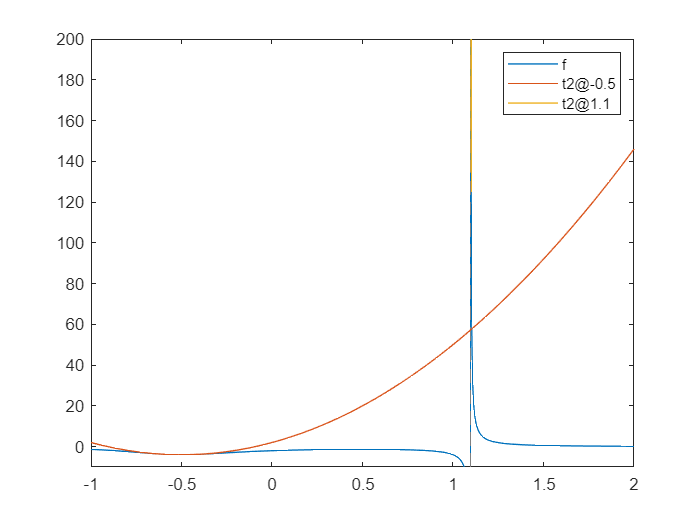

clear vars
syms x
f = 1/(x^3 - (3/4)*x - 1/2);
t1 = taylor(f, x, -0.5, 'Order', 3);
t2 = taylor(f, x, 1.1, 'Order', 3);
fplot([f, t1, t2], [-1, 2])
legend('f', 't2@-0.5', 't2@1.1')
ylim([-10, 200]);

Since $x=1\ldotp 1$ is very close to the vertical asymptote of the original function, we cannot see how well these approximations do in the same graph so let's take a closer look at each one individually.

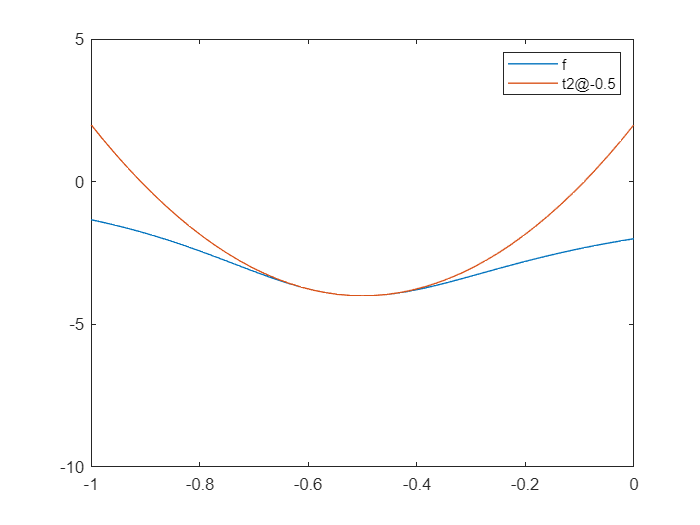

fplot([f, t1], [-1, 0])
legend('f', 't2@-0.5')
ylim([-10, 5]);

As we can see, the taylor expansion around $x=-0\ldotp 5$ fits the original curve of $f$ very nicely and can reasonably approximate a small neighborhood around $-0\ldotp 5$.

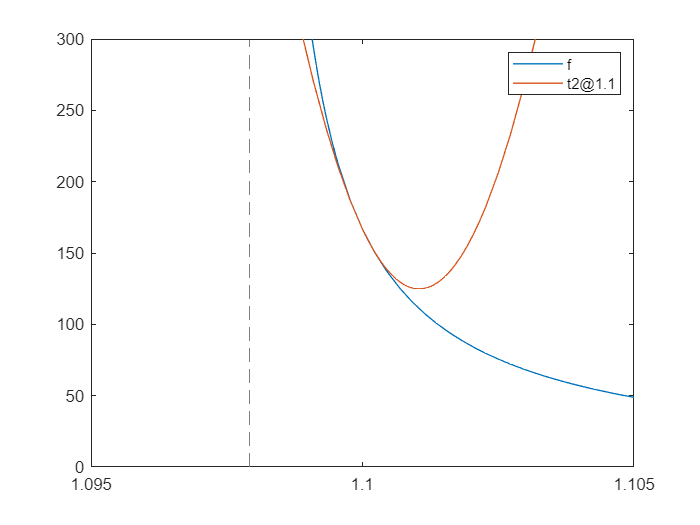

fplot([f, t2], [1.095, 1.105])
legend('f', 't2@1.1')
ylim([0, 300]);

Taking into account the fact that the x-axis has been severely scaled down to accomodate for the fluctuations around $x=1\ldotp 1$ we can see that this second order expansion can also fit the original curve although on a much smaller interval of $x$. The reason for this is likely the fact that the curvature of the function is extremely steep around its vertical asymptote which makes it difficult to approximate with a second degree function that is inherently devoid of any asymptotes. Therefore, a best effort with a second order Taylor expansion can only fit a small neighborhood around the point at which the expansion was performed.